## Preparando Datos

ds = datastore("../Datasets","ReadVariableNames",false);
data = generateData(ds);

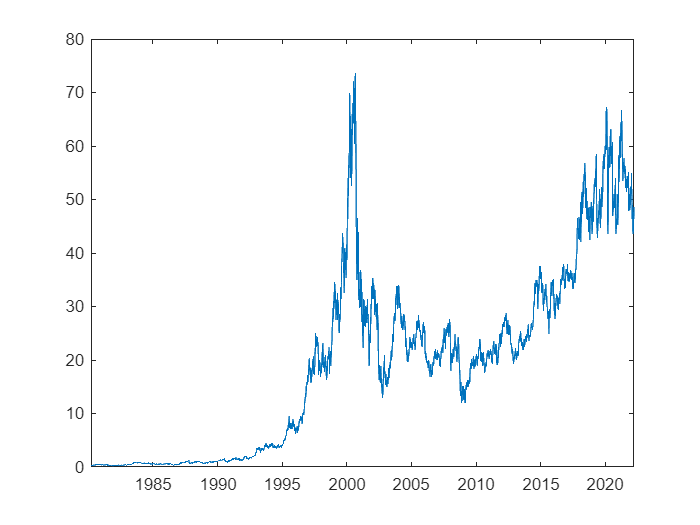


a =

     []


ans =

     []



compania = "INTEL";
datos = find(data.eti == compania);
test = data(datos(1):datos(end),:);
grafic(test)

Funciones de Ayuda

function eti = generateLabels(label,size)
    eti = [];
    for i = 1:size
        eti = [eti ;label];
    end
    eti = table(eti);
end

function data = generateData(ds)
names = ds.Files;
[numFiles,~] = size(names);
files = [];
variables = [];
Tables = [];
for i = 1:numFiles
    nombre = string(names(i));
    table = readtable(nombre);
    variables = [variables table.Properties.VariableNames];
end
headers =  unique(variables);
[row,column] = size(headers);
uniqueHeaders = [];
for i = 1:column
    indices= find (variables== string(headers(i)));
    [~,occurrence] = size(indices);
    if occurrence == numFiles
        uniqueHeaders = [uniqueHeaders string(headers(i))];
    end
end
data = [];
for i = 1:numFiles
    tab = [];
    nombre = string(names(i));
    lastCSV = strfind(nombre,".csv");
    label = extractBetween(nombre,100,lastCSV-1);
    table = readtable(nombre);
    cabeceras = table.Properties.VariableNames;
    [~,num] = size(uniqueHeaders);
    for j = 1:num
        coin = find(cabeceras == uniqueHeaders(j));
        tab = [tab table(:,coin)];
    end
    [rows,~] = size(tab);
    tab = [tab generateLabels(label,rows)];
    data = [data;tab];
end
end

function a = grafic(data)
    plot(data.Date,data.Low)
    a = []
end
